clear all
%Nate
load('nate weld 2 circles.mat')
%stackedplot(Acceleration)
TR = timerange("dec/09/2021 14:18:15","dec/09/2021 14:18:25");

clear all
%Nate
load('nate stitch 1.mat')
%stackedplot(Acceleration)
TR = timerange("dec/09/2021 14:12:00","dec/09/2021 14:12:10");

clear all
%Zeno
load('zeno weld 3 circle pull.mat')
%stackedplot(Acceleration)
TR = timerange("dec/09/2021 13:53:30","dec/09/2021 13:53:40");

clear all
%Zeno
load('zeno weld 2 stitch.mat')
%stackedplot(Acceleration)
TR = timerange("dec/09/2021 13:49:03","dec/09/2021 13:49:13");

clear all
%Owen
load('owenpractice.mat')
%stackedplot(Acceleration)
TR = timerange("dec/09/2021 13:36:40","dec/09/2021 13:36:50");

clear all
%Owen Weld 2
load('owen weld 2.mat')
TR = timerange("dec/09/2021 13:42:30","dec/09/2021 13:42:40");

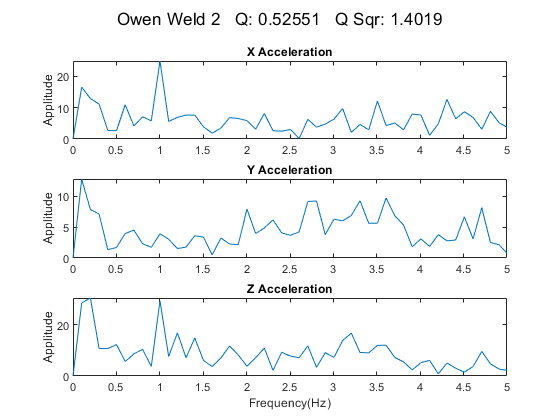

plt_label = 'Owen Weld 2';
[freqs_shifted_hz, X_Acc, Y_Acc, Z_Acc] = detrend_and_hz(Acceleration, TR); %detrends data and instanciates X, y, and Z acceleration
quality = weld_quality(X_Acc, Y_Acc, Z_Acc, freqs_shifted_hz); %our metric for determining weld quality, scale from 0-1 with lower number being better
quality_sqr = weld_quality_sqr(X_Acc, Y_Acc, Z_Acc, freqs_shifted_hz);
plot_w_subplot(X_Acc, Y_Acc, Z_Acc, freqs_shifted_hz, plt_label, quality, quality_sqr) %plots the data from 0-5hz
saveas(gcf, plt_label, 'jpg')

function [freqs_shifted_hz, X_Acc, Y_Acc, Z_Acc] = detrend_and_hz(Acceleration, TR)
...detrends data and sets up frequency for ploting and analysis
    DR = Acceleration(TR,:);
    X_Acc = table2array(DR(:,1));
    Y_Acc = table2array(DR(:,2));
    Z_Acc = table2array(DR(:,3));

    X_Acc = detrend(X_Acc);
    Y_Acc = detrend(Y_Acc);
    Z_Acc = detrend(Z_Acc);

    N = size(X_Acc,1);
    Fs = 100;
    %ind = linspace(0, 2*pi*(N-1)/N, N);
    %freqs = linspace(0, 2*pi*(N-1)/N, N);
    freqs_shifted_radians_per_sample = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
    freqs_shifted_radians_per_second = freqs_shifted_radians_per_sample*Fs;
    freqs_shifted_hz = freqs_shifted_radians_per_second/(2*pi);      
end
    
    
function [quality] = weld_quality(X_Acc, Y_Acc, Z_Acc, freqs_shifted_hz)
...takes in Acceleration data in three axis, and return the normalized variance from our .7hz expected frequency...
    X_fft = abs(fftshift(fft(X_Acc)));
    Y_fft = abs(fftshift(fft(Y_Acc)));
    Z_fft = abs(fftshift(fft(Z_Acc)));
    
   X_fft_trim = X_fft(500:550, :)/max(X_fft(500:550, :));
    Y_fft_trim = Y_fft(500:550, :)/max(Y_fft(500:550, :));
    Z_fft_trim = Z_fft(500:550, :)/max(Z_fft(500:550, :));
    Net_Acc_trim = ((X_fft_trim + Y_fft_trim + Z_fft_trim)/3)';
    freqs_shifted_hz_trim = freqs_shifted_hz(:, 500:550);
    
    %standard_deviation = zeros(50);
    for n = linspace(1, 50, 50)
        standard_deviation(n) = abs(((freqs_shifted_hz_trim(n))-.7))*(Net_Acc_trim(n));
    end
    quality = mean(standard_deviation);
end

function [quality_sqr] = weld_quality_sqr(X_Acc, Y_Acc, Z_Acc, freqs_shifted_hz)
...takes in Acceleration data in three axis, and return the normalized variance from our .7hz expected frequency...
    X_fft = abs(fftshift(fft(X_Acc)));
    Y_fft = abs(fftshift(fft(Y_Acc)));
    Z_fft = abs(fftshift(fft(Z_Acc)));
    
   X_fft_trim = X_fft(500:550, :)/max(X_fft(500:550, :));
    Y_fft_trim = Y_fft(500:550, :)/max(Y_fft(500:550, :));
    Z_fft_trim = Z_fft(500:550, :)/max(Z_fft(500:550, :));
    Net_Acc_trim = ((X_fft_trim + Y_fft_trim + Z_fft_trim)/3)';
    freqs_shifted_hz_trim = freqs_shifted_hz(:, 500:550);
    
    %standard_deviation = zeros(50);
    for n = linspace(1, 50, 50)
        standard_deviation(n) = (((freqs_shifted_hz_trim(n))-.7)^2)*(Net_Acc_trim(n));
    end
    quality_sqr = mean(standard_deviation);
end

function [] = plot_w_subplot(X_Acc, Y_Acc, Z_Acc, freqs_shifted_hz, plot_label, quality, quality_sqr)
    ...plots fft of data from 0-5hz in the X Y and Z axis
    subplot(3,1,1)
    plot(freqs_shifted_hz, abs(fftshift(fft(X_Acc))))
    title('X Acceleration')
    ylabel('Applitude')
    xlim([0 5])
    
    subplot(3,1,2)
    plot(freqs_shifted_hz, abs(fftshift(fft(Y_Acc))))
    title('Y Acceleration')
    ylabel('Applitude')
    xlim([0 5])
    
    subplot(3,1,3)
    plot(freqs_shifted_hz, abs(fftshift(fft(Z_Acc))))
    title('Z Acceleration')
    xlabel('Frequency(Hz)')
    ylabel('Applitude')
    xlim([0 5])
    
    plt_title = [plot_label '   Q: ' num2str(quality) '   Q Sqr: ' num2str(quality_sqr)];
    sgtitle(plt_title)
end
